# Channel Estimation

clear all; close all; clc;
%%%%% OFDM parameters %%%%%
params.del_f = 1e4;              % subcarrier spacing = 10kHz
params.numCarriers = 512;        % fft size = 512
params.prefixDuration = 6.25e-6; % CP duration =6.25 mus

params.sampleRate = params.del_f * params.numCarriers;
params.prefixLength = round(params.prefixDuration * params.sampleRate);
params.blockDuration = (params.numCarriers + params.prefixLength) / params.sampleRate;
params.preamblePeriodicity = 5;               % Frame size = 5
params.lowerGuardTones = -255:-241;
params.upperGuardTones = 241:256;
params.guardTones = [params.lowerGuardTones params.upperGuardTones];   % Guard bands
params.DCSubcarrier = [0];                   % DC carrier
params.pilots = true;
params.pilotPeriodicity = 8;

%%%% Channel Parameters %%%%%
params.pathGains = [-3 0 -1 -4 -9 -17];
params.delays = [0 7 13 18 21 26];
% Taps = 16;
% params.delays = 1:Taps;
% params.pathGains = zeros([1 Taps]);

% params.CFO = 28.65e3;                      % Maximum offset = 28.65kHz
params.CFO = 0;                      % Maximum offset = 28.65kHz
params.SNR = 100;

%%%%% Modulation parameters %%%%%
params.modulationType = 'QAM';
params.modulationOrder = 4;
params.numFrames = 2;

%%%%% Channel estimation %%%%%
params.estimationType = "ZF";
% params.estimationType = "ZF_LINEAR_INTERPOLATE";
% params.estimationType = "ZF_FFT_INTERPOLATE";
% params.estimationType = "mLS";
% params.estimationType = "mLS_INFORMED";

%%%%% Simulation %%%%%
S = OFDM.generateOFDMframe(params);
s = OFDM.modulate(S, params);
[r, h] = OFDM.channel(s, params);
% r = s;
h

h =   -0.4661 - 0.2684i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.5703 - 0.1870i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.6033 - 0.0779i
   0.0000 + 0.0000i


R = OFDM.demodulate(r, params);

hest = OFDM.channelEstimate(R, params)

hest =   -0.0602 - 0.0332i  -0.0602 - 0.0332i  -0.0602 - 0.0332i  -0.0602 - 0.0332i  -0.0602 - 0.0332i  -0.0602 - 0.0332i  -0.0602 - 0.0332i  -0.0602 - 0.0332i
   0.0023 - 0.0003i   0.0023 - 0.0003i   0.0023 - 0.0003i   0.0023 - 0.0003i   0.0023 - 0.0003i   0.0023 - 0.0003i   0.0023 - 0.0003i   0.0023 - 0.0003i
  -0.0027 + 0.0004i  -0.0027 + 0.0004i  -0.0027 + 0.0004i  -0.0027 + 0.0004i  -0.0027 + 0.0004i  -0.0027 + 0.0004i  -0.0027 + 0.0004i  -0.0027 + 0.0004i
   0.0030 - 0.0004i   0.0030 - 0.0004i   0.0030 - 0.0004i   0.0030 - 0.0004i   0.0030 - 0.0004i   0.0030 - 0.0004i   0.0030 - 0.0004i   0.0030 - 0.0004i
  -0.0034 + 0.0005i  -0.0034 + 0.0005i  -0.0034 + 0.0005i  -0.0034 + 0.0005i  -0.0034 + 0.0005i  -0.0034 + 0.0005i  -0.0034 + 0.0005i  -0.0034 + 0.0005i
   0.0037 - 0.0005i   0.0037 - 0.0005i   0.0037 - 0.0005i   0.0037 - 0.0005i   0.0037 - 0.0005i   0.0037 - 0.0005i   0.0037 - 0.0005i   0.0037 - 0.0005i
  -0.0040 + 0.0006i  -0.0040 + 0.0006i  -0.0040 + 0.0006i  -0.0040 + 0.0006

mse = OFDM.channelMSE(h, hest,params)

mse = 1.2375e-10

mse_db = 10*log10(mse)

mse_db = -99.0744

## PLOT

snrs = 0: 3: 30;
estimationTypes = ["ZF","ZF_LINEAR_INTERPOLATE", "ZF_FFT_INTERPOLATE", "mLS", "mLS_INFORMED"];
mses = zeros([length(estimationTypes) length(snrs)]);
Ntrials = 100;

for n = 1:Ntrials
    S = OFDM.generateOFDMframe(params);
    s = OFDM.modulate(S, params);
    
    for i = 1:length(snrs)
        params.SNR = snrs(i);
        %%%%% Simulation %%%%%
        [r, h] = OFDM.channel(s, params);
        R = OFDM.demodulate(r, params);
    
        for j = 1:length(estimationTypes)
            params.estimationType = estimationTypes(j);
            hest = OFDM.channelEstimate(R, params);
            mses(j, i) = mses(j, i) + OFDM.channelMSE(h, hest,params);
        end
    end
end
mses = mses / Ntrials;
mses_db = 10*log10(mses)

mses_db =     4.0443    0.3592   -2.7990   -5.1311   -8.3613  -11.3742  -14.2520  -17.2234  -19.9653  -22.9007  -26.3177
    2.5044   -1.0019   -3.8564   -5.6857   -7.8032   -9.4489  -10.3429  -10.8025  -11.2508  -11.5921  -11.6910
    4.0519    0.3725   -2.7622   -5.0633   -8.2041  -11.1044  -13.7248  -16.2008  -18.0926  -19.7898  -21.4209
    1.1683   -2.5214   -5.7001   -8.0187  -11.2517  -14.2554  -17.1567  -20.1279  -22.8520  -25.7841  -29.2048
   -5.9307   -9.6229  -12.9548  -15.3010  -18.5765  -21.4379  -24.3344  -27.2629  -30.1305  -32.9838  -36.2969


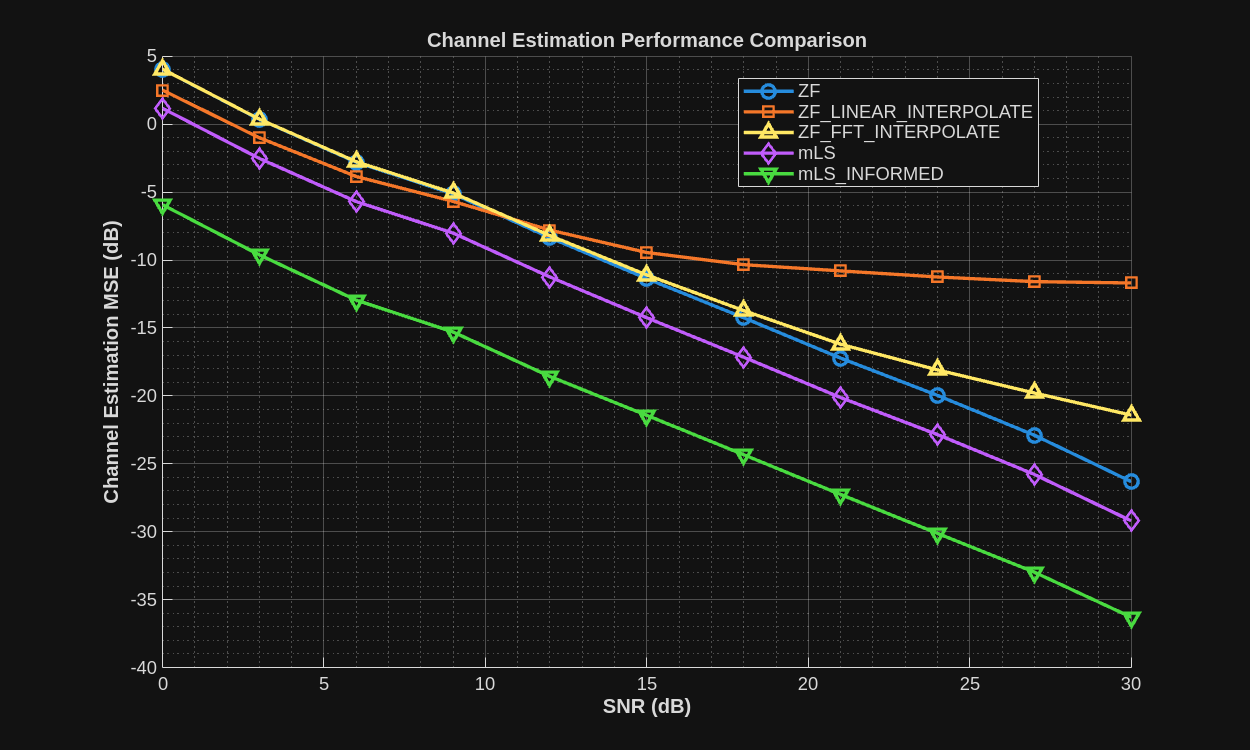

OFDM.plotChannelEstimationPerformance(snrs,mses, estimationTypes)